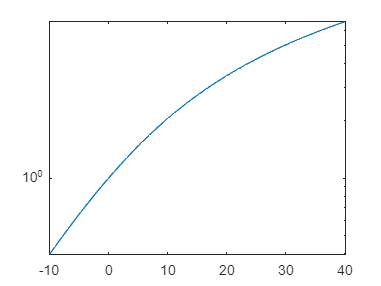

%shanono sudai

x = [];
y = [];

R = 1e6;
B = 2e6;
xx = [];
yy = [];

for i = -10:0.2:40
    x = [x, i];
    db2mag(i);
    y = [y, log2(1+db2mag(i))];

    xx = [xx, i];
    yy = [yy, B * log2(1+db2pow(i))];


end
figure
semilogy(x, y)

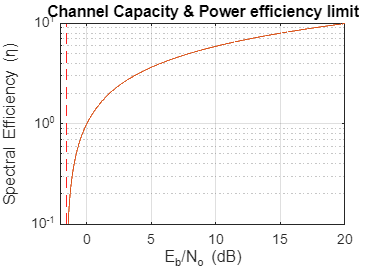


figure


figure
semilogy(xx, yy)
hold on
k =0.1:0.001:15; EbN0=(2.^k-1)./k;
semilogy(10*log10(EbN0),k);
hold off
xlabel('E_b/N_o (dB)');ylabel('Spectral Efficiency (\eta)');
title('Channel Capacity & Power efficiency limit')
hold on;grid on; xlim([-2 20]);ylim([0.1 10]);
yL = get(gca,'YLim');
line([-1.59 -1.59],yL,'Color','r','LineStyle','--');